## **Driver test program to check Clothoids library**

**Test lines**

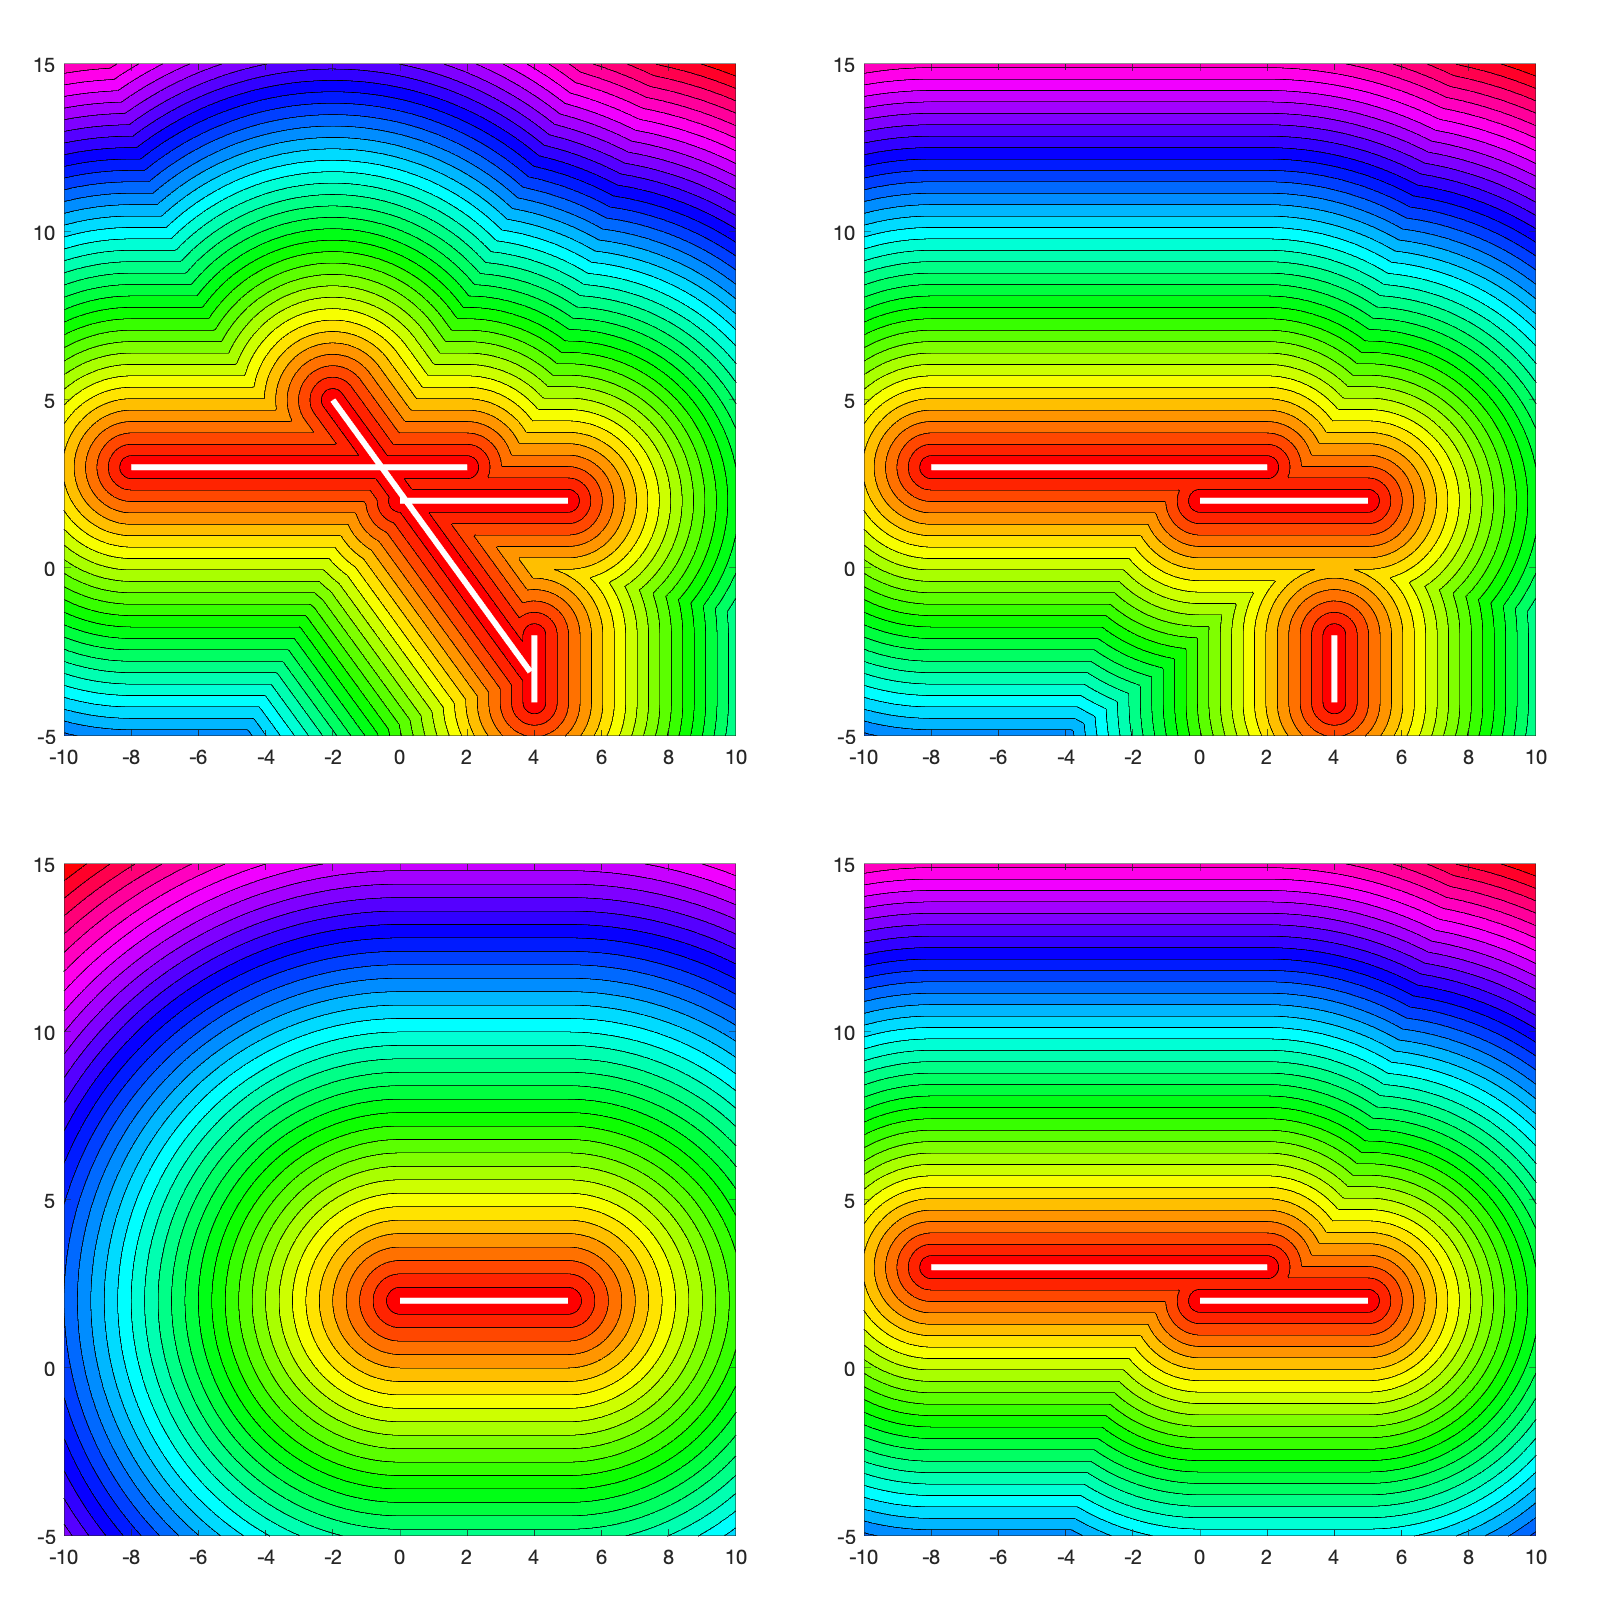

Elapsed time is 0.003562 seconds.


Elapsed time is 0.003338 seconds.


Elapsed time is 0.003954 seconds.


Elapsed time is 0.003243 seconds.


close all;

% check constructors
x0     = [0,2,4,-2];
y0     = [2,3,-4,5];
theta0 = [0,pi,pi/2,-0.3*pi];
L      = [5,10,2,10];

aa = 0.04;
bb = 0.5-2*aa;

figure('Position',[ 1 1 800 800]);

LINE = {};
for kk=1:4

  switch(kk)
  case 1; subplot('Position',[aa aa bb bb]);
  case 2; subplot('Position',[aa+0.5 aa bb bb]);
  case 3; subplot('Position',[aa+0.5 aa+0.5 bb bb]);
  case 4; subplot('Position',[aa aa+0.5 bb bb]);
  end

  LINE{kk} = LineSegment( x0(kk), y0(kk), theta0(kk), L(kk) );

  x = -10:0.05:10;
  y = -5:0.05:15;
  [X,Y] = meshgrid(x,y);

  tic
  if kk > 1
    Z = min(Z,LINE{kk}.distance(X,Y));
  else
    Z = LINE{kk}.distance(X,Y);
  end
  toc

  colormap(hsv);
  contourf(X,Y,Z,40);
  %surf(X,Y,Z)
  axis equal;

  hold on;
  for i=1:kk
    LINE{i}.plot('Color','white','Linewidth',3);
  end
  %
end